# Multiworkspace PD analysis

Create iris plots and compute likelihoods of PD distributions

## Add libraries to path

if(ispc)
    homeFolder = 'C:\Users\Raeed\';
else
    homeFolder = '/home/raeed/';
end
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'MultiWorkspace' filesep 'lib' filesep])
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'MultiWorkspace' filesep 'SplitWS' filesep 'Han' filesep '20160322' filesep 'area2' filesep])

## Load CDS files

cds_files = dir(['CDS' filesep '*.mat']);

for i = 1:numel(cds_files)
    load(['CDS' filesep cds_files(i).name])
end

clear i
clear cds_files


## Add CDS files to experiments and bin data

% DL stuff
DL_ex = experiment();

% set variables to load from cds
DL_ex.meta.hasLfp=false;
DL_ex.meta.hasKinematics=true;
DL_ex.meta.hasForce=false;
DL_ex.meta.hasUnits=true;
DL_ex.meta.hasTrials=true;
DL_ex.meta.hasAnalog=true;
% add session to experiment
DL_ex.addSession(DL_cds);

% Bin experiment data
DL_ex.binConfig.include(1).field='units';
DL_ex.binConfig.include(1).which=find([DL_ex.units.data.ID]>0 & [DL_ex.units.data.ID]<255);
DL_ex.binConfig.include(2).field='kin';
DL_ex.binConfig.include(2).which={};
DL_ex.binConfig.include(3).field='analog';
DL_ex.binConfig.include(3).which=DL_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
DL_ex.firingRateConfig.cropType='tightCrop';
DL_ex.firingRateConfig.offset=-0.015;

DL_ex.binData()


% PM stuff
PM_ex = experiment();

% set variables to load from cds
PM_ex.meta.hasLfp=false;
PM_ex.meta.hasKinematics=true;
PM_ex.meta.hasForce=false;
PM_ex.meta.hasUnits=true;
PM_ex.meta.hasTrials=true;
PM_ex.meta.hasAnalog=true;
% add session to experiment
PM_ex.addSession(PM_cds);

PM_ex.binConfig.include(1).field='units';
PM_ex.binConfig.include(1).which=find([PM_ex.units.data.ID]>0 & [PM_ex.units.data.ID]<255);
PM_ex.binConfig.include(2).field='kin';
PM_ex.binConfig.include(2).which={};
PM_ex.binConfig.include(3).field='analog';
PM_ex.binConfig.include(3).which=PM_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
PM_ex.firingRateConfig.cropType='tightCrop';
PM_ex.firingRateConfig.offset=-0.015;

PM_ex.binData()

## Clear CDS files

clear *_cds

## Calculate DL PDs

% DL_ex.bin.pdConfig.units = [];
% DL_ex.bin.pdConfig.windows = something that only uses successful trials...
DL_ex.bin.pdConfig.method = 'glm';
DL_ex.bin.pdConfig.pos = true;
DL_ex.bin.pdConfig.vel = true;
DL_ex.bin.pdConfig.force = false;
DL_ex.bin.pdConfig.speed = true;
DL_ex.bin.pdConfig.bootstrapReps = 100;
DL_ex.bin.fitPds()

starting GLM based PD computation
LeftS1Area2CH1ID1:getting data subset(ET=6.9e-05s).  Bootstrapping GLM PD computation(ET=0.11288s).  Converting GLM weights to PDs(ET=32.0029s).
LeftS1Area2CH2ID1:getting data subset(ET=32.5659s).  Bootstrapping GLM PD computation(ET=32.5751s).  Converting GLM weights to PDs(ET=58.4481s).
LeftS1Area2CH4ID1:getting data subset(ET=58.8695s).  Bootstrapping GLM PD computation(ET=58.8779s).  Converting GLM weights to PDs(ET=83.9983s).
LeftS1Area2CH4ID2:getting data subset(ET=84.3648s).  Bootstrapping GLM PD computation(ET=84.3733s).  Converting GLM weights to PDs(ET=108.7216s).
LeftS1Area2CH4ID3:getting data subset(ET=109.0841s).  Bootstrapping GLM PD computation(ET=109.0923s).  Converting GLM weights to PDs(ET=135.1663s).
LeftS1Area2CH4ID4:getting data subset(ET=135.5765s).  Bootstrapping GLM PD computation(ET=135.5844s).  Converting GLM weights to PDs(ET=155.5275s).
LeftS1Area2CH5ID1:getting data subset(ET=155.8547s).  Bootstrapping GLM PD computation(ET

## Calculate PM PDs

% PM_ex.bin.pdConfig.units = [];
% PM_ex.bin.pdConfig.windows = something that only uses successful trials...
PM_ex.bin.pdConfig.method = 'glm';
PM_ex.bin.pdConfig.pos = true;
PM_ex.bin.pdConfig.vel = true;
PM_ex.bin.pdConfig.force = false;
PM_ex.bin.pdConfig.speed = true;
PM_ex.bin.pdConfig.bootstrapReps = 100;
PM_ex.bin.fitPds()

starting GLM based PD computation
LeftS1Area2CH1ID1:getting data subset(ET=0.000308s).  Bootstrapping GLM PD computation(ET=0.11734s).  Converting GLM weights to PDs(ET=28.301s).
LeftS1Area2CH2ID1:getting data subset(ET=28.6895s).  Bootstrapping GLM PD computation(ET=28.6986s).  Converting GLM weights to PDs(ET=54.6309s).
LeftS1Area2CH4ID1:getting data subset(ET=55.1354s).  Bootstrapping GLM PD computation(ET=55.1453s).  Converting GLM weights to PDs(ET=78.0854s).
LeftS1Area2CH4ID2:getting data subset(ET=78.4528s).  Bootstrapping GLM PD computation(ET=78.4612s).  Converting GLM weights to PDs(ET=101.2937s).
LeftS1Area2CH4ID3:getting data subset(ET=101.6581s).  Bootstrapping GLM PD computation(ET=101.6645s).  Converting GLM weights to PDs(ET=123.9513s).
LeftS1Area2CH4ID4:getting data subset(ET=124.419s).  Bootstrapping GLM PD computation(ET=124.4296s).  Converting GLM weights to PDs(ET=145.4272s).
LeftS1Area2CH5ID1:getting data subset(ET=145.7586s).  Bootstrapping GLM PD computation(ET=

  Converting GLM weights to PDs(ET=371.7286s).
LeftS1Area2CH25ID1:getting data subset(ET=372.1496s).  Bootstrapping GLM PD computation(ET=372.156s).  Converting GLM weights to PDs(ET=393.4145s).
LeftS1Area2CH26ID1:getting data subset(ET=393.7455s).  Bootstrapping GLM PD computation(ET=393.7514s).  Converting GLM weights to PDs(ET=414.8088s).
LeftS1Area2CH30ID1:getting data subset(ET=415.1549s).  Bootstrapping GLM PD computation(ET=415.1613s).  Converting GLM weights to PDs(ET=436.3205s).
LeftS1Area2CH31ID1:getting data subset(ET=436.6454s).  Bootstrapping GLM PD computation(ET=436.6515s).  Converting GLM weights to PDs(ET=458.9647s).
LeftS1Area2CH33ID1:getting data subset(ET=459.308s).  Bootstrapping GLM PD computation(ET=459.3152s).  Converting GLM weights to PDs(ET=481.5745s).
LeftS1Area2CH36ID1:getting data subset(ET=481.9682s).  Bootstrapping GLM PD computation(ET=481.9738s).  Converting GLM weights to PDs(ET=500.4549s).
LeftS1Area2CH37ID1:getting data subset(ET=500.7515s).  Bootst

## Save experiments

save('ExData/DL_ex.mat','DL_ex')

Out Of Memory during serialization of the Subsystem Data


Error using save
Error closing file /home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/ExData/DL_ex.mat.
The file may be corrupt.

save('ExData/PM_ex.mat','PM_ex')


## Plot PM and DL handle positions

PMpos = [PM_ex.kin.data.x PM_ex.kin.data.y];
DLpos = [DL_ex.kin.data.x DL_ex.kin.data.y];

figure

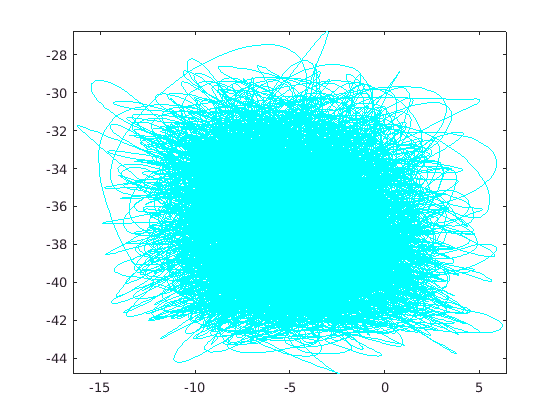

plot(PMpos(:,1),PMpos(:,2),'c-')
axis equal

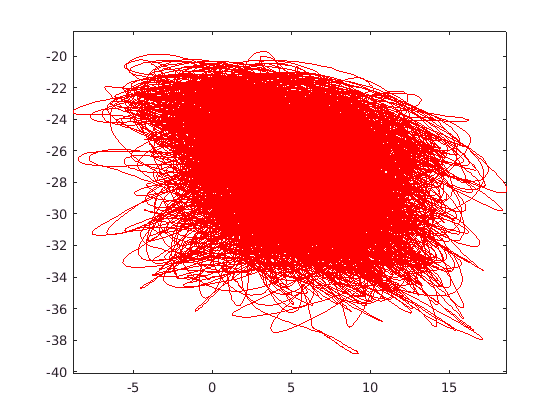

figure
plot(DLpos(:,1),DLpos(:,2),'r-')
axis equal

## Make Iris plot

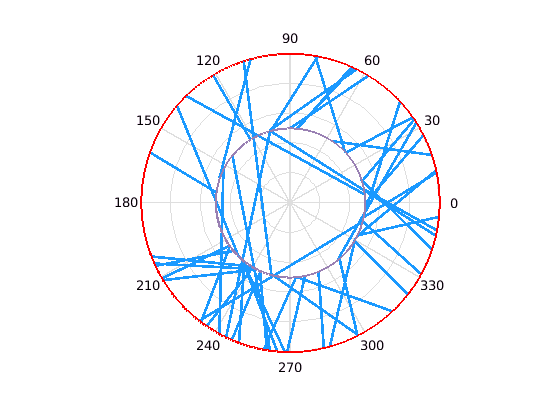

figure
irisPlot(PM_ex.bin,DL_ex.bin)

## Plot histogram of PD differences

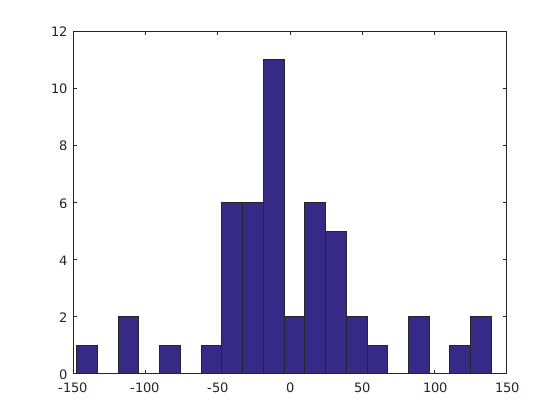

figure
angsDiff = angsDLtuned-angsPMtuned; % This is left over from before
angsDiff(angsDiff<-pi) = angsDiff(angsDiff<-pi)+2*pi;
angsDiff(angsDiff>pi) = angsDiff(angsDiff>pi)-2*pi;
hist(angsDiff*180/pi,20)

## Simulate neurons from muscle lengths and joint angles

% set neural weights
joint_weights = randn(8,100); % 7 joints + baseline firing
muscle_weights = randn(40,100); % 39 muscles + baseline firing

% extract joint angles and muscle positions
% joint_idx = 10:16;
muscle_idx = 16:54; %%%%%%% This index needs to be updated
tsPM = PM_ex.bin.data.t;
tsDL = DL_ex.bin.data.t;
% PM_joint_pos = PM_ex.bin.data(:,joint_idx);
PM_muscle_pos = PM_ex.bin.data(:,muscle_idx);
PM_muscle_vel = PM_muscle_pos;
% DL_joint_pos = DL_ex.bin.data(:,joint_idx);
DL_muscle_pos = DL_ex.bin.data(:,muscle_idx);
DL_muscle_vel = DL_muscle_pos;

% get joint and muscle velocities
for i = 1:width(PM_muscle_pos)
    PM_muscle_vel{:,i} = gradient(PM_muscle_pos{:,i},tsPM);
end
for i = 1:width(DL_muscle_pos)
    DL_muscle_vel{:,i} = gradient(DL_muscle_pos{:,i},tsDL);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% Normalize? %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% not sure...
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% simulate neural activity
simFRPM = PM_muscle_vel{:,:}*muscle_weights;
simFRDL = DL_muscle_vel{:,:}*muscle_weights;

% make fake binnedData objects for DL and PM, fill with simulated neural activity.
PM_muscle_bin = binnedData();

DL_muscle_bin = binnedData();

oldPMbinData = PM_ex.bin.data;
oldDLbinData = DL_ex.bin.data;


% Calculate PDs on simulated neural activity
PM_muscle_bin.pdConfig.method = 'lm';
PM_muscle_bin.pdConfig.pos = true;
PM_muscle_bin.pdConfig.vel = true;
PM_muscle_bin.pdConfig.force = false;
PM_muscle_bin.pdConfig.speed = true;
PM_muscle_bin.pdConfig.bootstrapReps = 100;
PM_muscle_bin.fitPds()

DL_muscle_bin.pdConfig.method = 'lm';
DL_muscle_bin.pdConfig.pos = true;
DL_muscle_bin.pdConfig.vel = true;
DL_muscle_bin.pdConfig.force = false;
DL_muscle_bin.pdConfig.speed = true;
DL_muscle_bin.pdConfig.bootstrapReps = 100;
DL_muscle_bin.fitPds()

% Iris plot
figure
irisPlot(PM_muscle_bin,DL_muscle_bin)

